%Weigthed topology C(w_ij)
    %CHOOSE THE REPRESENTATION YOU WANT TO VISUALIZE BY UNCOMMENTING THE
    %CODE LINES
    %THEN, SIMPLY RUN THE CODE.
clear all;
tic

%Generate the data
band = ["alpha"]; %You can try 'alpha' or 'beta'
gband='\alpha ';%You can try '\alpha' or '\beta';


% type='rois';
% type='215nodes';
% type='1202nodes';

%Number of random surrogates
N=5;


type = "rois"

band = "alpha"

type = "rois"

band = "beta"

type = "215nodes"

band = "alpha"

type = "215nodes"

band = "beta"

type = "1202nodes"

band = "alpha"

type = "1202nodes"

band = "beta"

## **SAVE VARIABLES**

names = {'C','L','Raw_C','Raw_L'};
c = cell(length(names),1);
results_boys = cell2struct(c,names);
results_girls = cell2struct(c,names);

## 78X78 REPRESENTATION

if(strcmp(type,'rois')==1)
dum = sprintf('../plv_78ROIs/sexy_cn_312s_plv_78_%s_%s.mat',type,band);

## 215X215 REPRESENTATION

elseif (strcmp(type,'215nodes')==1)
dum = sprintf('../plv_215/sexy_cn_312s_plv_%s_%s.mat',type,band);

## 1202 x 1202 REPRESENTATION

elseif(strcmp(type,'1202nodes')==1)
dum = sprintf("../plv_nodes/sexy_cn_312s_plv_%s_%s.mat",type,band);
end

%Load the selected representation
files=dir(dum);
filename=horzcat(files.folder,'/',files.name);

load(filename);

%Filter betweeen boys and Girls
boys = sample.neuro_vals(:,2) == 1; %Boys logical array
girls = sample.neuro_vals(:,2) == 2; %Girls logical array

boy_rois = load_ROIs(boys, fcmatrix); %Boys ROIs matrix
girl_rois = load_ROIs(girls, fcmatrix); %Girls ROIs matrix
k = 1;



%Computation of the clustering coefficient and spl. 
for i=1:length(find(boys))
    ad_boys=boy_rois(:,:,i);
    g_boys = graph(1./ad_boys,'omitselfloops'); %ignores the diagonal entries, weights are inverted
   
    C_boys(i) = mean(clustering_coef_wu(ad_boys));
    D_boys = distances(g_boys,'Method','positive');
    dist_boys(i)= mean(D_boys(D_boys>0),'omitnan');
    deg_boys(i)=mean(strengths_und(ad_boys));

    [~,~,vals]=find(triu(ad_boys,1));
    for k =1:N
        %N permutations of the initial adjacency matrix
        rng('shuffle');               
        ranvals=vals(randperm(length(vals)));
        ad_rand_b=triu(ad_boys);
        ad_rand_b((logical(triu(ad_rand_b,1))))=ranvals;
        ad_rand_b=ad_rand_b+ad_rand_b';
        
        G_R =graph(1./ad_rand_b,'omitselfloops');%,'upper');
        C_rand_b(k) = mean(clustering_coef_wu(ad_rand_b));
        D_rand_b = distances(G_R,'Method','positive');
        dist_rand_b(k)= mean(D_rand_b(D_rand_b>0),'omitnan');
        deg_rand_b(k) = mean(strengths_und(ad_rand_b));
    end 
    %mean value
    Cmean_rand_b(i) = mean(C_rand_b);
    distmean_rand_b(i) = mean(dist_rand_b);
    degmean_rand_b(i) = mean(deg_rand_b);  
    
   
end

%Save the results
results_boys.Raw_C= C_boys;
results_boys.Raw_L = dist_boys;
results_boys.C = C_boys./Cmean_rand_b;
results_boys.L = dist_boys./distmean_rand_b;

for i=1:length(find(girls))
    ad_girls=girl_rois(:,:,i);
    g_girls = graph(1./ad_girls,'omitselfloops'); %ignores the diagonal entries, weights are inverted

    C_girls(i) = mean(clustering_coef_wu(ad_girls));
    D_girls =distances(g_girls,'Method','positive');
    dist_girls(i)= mean(D_girls(D_girls>0),'omitnan');
    deg_girls(i) = mean(strengths_und(ad_girls));

    
    [~,~,vals]=find(triu(ad_girls,1));
    for k = 1:N
       %For each network, we produce a random network with the same
        %properties
        rng('shuffle');
        
        ranvals=vals(randperm(length(vals)));
        ad_rand_g=triu(ad_girls);
        ad_rand_g((logical(triu(ad_rand_g,1))))=ranvals;
        ad_rand_g=ad_rand_g+ad_rand_g';

        G_R =graph(1./ad_rand_g,'omitselfloops');%,'upper');

        C_rand_g(k) = mean(clustering_coef_wu(ad_rand_g));
        D_rand_g = distances(G_R,'Method','positive');
        dist_rand_g(k)= mean(D_rand_g(D_rand_g>0),'omitnan');
        deg_rand_g(k) = mean(strengths_und(ad_rand_g));
    end 
    Cmean_rand_g(i) = mean(C_rand_g);
    distmean_rand_g(i) = mean(dist_rand_g);
    degmean_rand_g(i) = mean(deg_rand_g);
end

%Save the results
results_girls.Raw_C= C_girls;
results_girls.Raw_L = dist_girls;
results_girls.C = C_girls./Cmean_rand_g;
results_girls.L = dist_girls./distmean_rand_g;


mkdir(sprintf('%s/%s',type,band))

save(sprintf('%s/%s/boys.mat',type,band),"results_boys")
save(sprintf('%s/%s/girls.mat',type,band),"results_girls")


# VISUALIZATION OF RESULTS

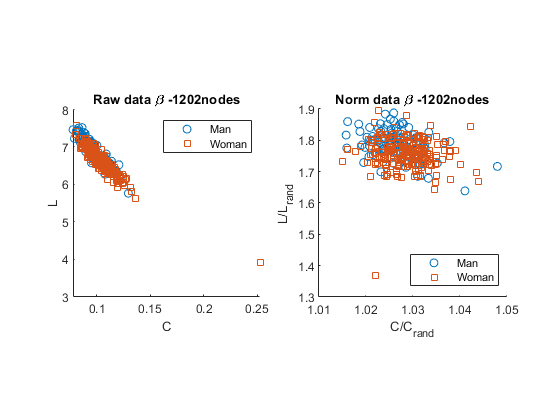

% %Run from here if you have already downloaded/generated the results
% 
%Generate the data
clear all;
band = ["beta"]; %You can try 'alpha' or 'beta'
gband='\beta ';%You can try '\alpha' or '\beta';

% type='rois';
% type='215nodes';
type='1202nodes';

load(sprintf('%s/%s/boys.mat',type,band));
load(sprintf('%s/%s/girls.mat',type,band));

%Boys
C_boys = results_boys.Raw_C;
dist_boys = results_boys.Raw_L; 
C_b = results_boys.C;
L_b = results_boys.L; 
%Girls
C_girls = results_girls.Raw_C;
dist_girls = results_girls.Raw_L; 
C_g = results_girls.C;
L_g = results_girls.L; 

figure();
%C vs dist 
subplot(1,2,1),hold on;
plot(C_boys,dist_boys,'o')
plot(C_girls,dist_girls,'s')
%axis([0 0.5 3 9])
legend('Man', 'Woman')
xlabel('C')
ylabel('L')
tit=sprintf('Raw data %s-%s',gband,type);
title(tit)
axis square
hold off;
% 
subplot(1,2,2),hold on
plot(C_b,L_b,'o')
plot(C_g,L_g,'s')
%axis([0.95 1.05 1. 2])

legend('Man', 'Woman','Location','southeast')
xlabel('C/C_{rand}')
ylabel('L/L_{rand}')

tit=sprintf('Norm data %s-%s',gband,type);
title(tit)
axis square
hold off;


% filename=sprintf('L_vs_C_%s_%s_surrog%d.pdf',band,type,N);
% print('-dpdf',filename,'-bestfit')
toc

Elapsed time is 28535.944692 seconds.


function sex_ROIs =load_ROIs(sex, fcmatrix)
%Load the ROI's matrix and format them
%Arguments: sex -> Logical array
%fcmatrix: 4D array (Database of MEG)
    %Load
    nROIs=size(fcmatrix,1);%Network size
    nsubjects=sum(sex);%Number of subjects of each sex type
    sex_ROIs = zeros(nROIs,nROIs,nsubjects);%esta linea se puede borrar
    sex_ROIs = fcmatrix(:,:,sex);
    ind=~logical(eye(nROIs));%indexes of the non diagonal elements     
    id=logical(eye(nROIs));%indexes of the diagonal elements
    %Format the matrix (Remove the diagonal)
    for i = 1:nsubjects
        
         %Linear normalization of the weights
        dum=sex_ROIs(:,:,i);        
        minval=min(dum(ind));%min value among the non diagonal elements
        maxval=max(dum(ind));%max value among the non diagonal elements
        meanval=mean(dum(ind));%mean value of all weights 

        %sex_ROIs(:,:,i) = (sex_ROIs(:,:,i)- min(min(sex_ROIs(:,:,i))))/(max(max(sex_ROIs(:,:,i))) - min(min(sex_ROIs(:,:,i))));
        dum = (dum-minval)./(maxval-minval);    
        %dum=dum./meanval; %testing another normalization 
        dum(id)=0;%setting diagonal elements to 0 -Note that in the ROI representation the element (40,40) is a NaN
        %sex_ROIs(:,:,i) = sex_ROIs(:,:,i) - diag(diag(sex_ROIs(:,:,i)));
        sex_ROIs(:,:,i)=dum;
    end   
end

function [str] = strengths_und(CIJ)
%STRENGTHS_UND        Strength
%
%   str = strengths_und(CIJ);
%
%   Node strength is the sum of weights of links connected to the node.
%
%   Input:      CIJ,    undirected weighted connection matrix
%
%   Output:     str,    node strength
%
%
%   Olaf Sporns, Indiana University, 2002/2006/2008

% compute strengths
str = sum(CIJ);        % strength
end

